## [Automation of Liquid Level Control](https://apmonitor.com/pdc/index.php/Main/LevelControl)

The objective of this case study is to automatically maintain a liquid level in the lower of two dual gravity drained tanks.

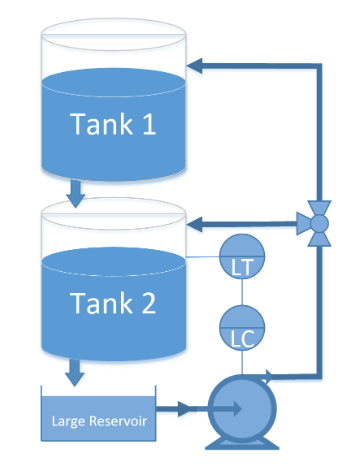

The exercise involves creating a dynamic first-order model, obtaining tuning parameters, and adjusting the PID tuning to achieve acceptable performance.

## Step Test with Graphical FOPDT Fit

For the gravity drained tank problem, conduct a step test by manipulating the pump rate and recording the level in the bottom tank. Use graphical methods to obtain a FOPDT model and report the values of the three parameters $(K_p, \tau_p, \theta_p)
$.

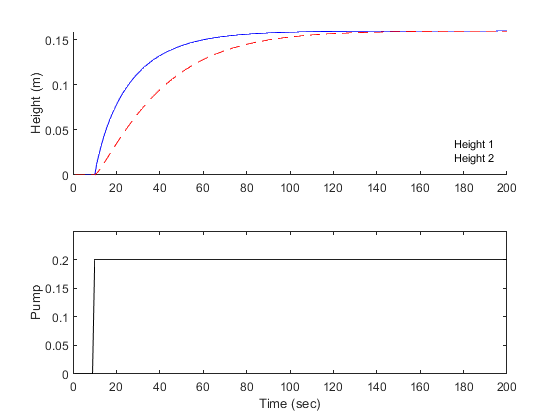

clear
clc
clf

% Initial conditions (levels)
h0 = [0.0,0.0];

% Time points to report the solution
tf = 200;
t = linspace(0,tf,tf+1);
% Inputs that can be adjusted
pump = zeros(1,tf+1);
% pump can operate between 0 and 1
pump(10:end) = 0.2;
% valve = 0, directly into top tank
% valve = 1, directly into bottom tank
valve = 0.0;
% Record the solution
y = zeros((tf+1),2);
y(1,:) = h0;

    
% Simulate the tank step test
for i = 1:tf
    
    % Integrate the model
%     h = odeint(tank,h0,[0,1],inputs);
    [t, h] = ode45(@(t, h) tank(t, h, pump(i), valve),[0,1],h0);
    % Record the result
    y(i+1,:) = h(end,:);
    % Reset the initial condition
    h0 = h(end,:);
end

% plot results


subplot(2,1,1)
hold on
p1 = plot(1:i,y(1:i,1),'b-');
p2 = plot(1:i,y(1:i,2),'r--');
ylabel('Height (m)')
legend([p1, p2], {'Height 1', 'Height 2'}, 'Location', 'best')


subplot(2,1,2)
plot(1:i,pump(1:i),'k-')
ylim([0, 0.25])

ylabel('Pump')
xlabel('Time (sec)')

function dhdt = tank(t, h, pump, valve)
    h1 = max(0.0, h(1));
    h2 = max(0.0, h(2));
    c1 = 0.08; % inlet valve coefficient
    c2 = 0.04; % tank outlet coefficient
    dhdt1 = c1 * (1.0-valve) * pump - c2 * sqrt(h1);
    dhdt2 = c1 * valve * pump + c2 * sqrt(h1) - c2 * sqrt(h2);
    % overflow conditions
    if h1>=1.0 && dhdt1>0.0
        dhdt1 = 0;
    end
    if h2>=1.0 && dhdt2>0.0
        dhdt2 = 0;
    end
    dhdt = [dhdt1, dhdt2]';
end

## Fit FOPDT with Optimization

Use optimization to obtain the same parameters in the FOPDT model (see Lesson 7). Compare the optimized values with those obtained graphically. Are they the same? Why or why not? Which values would you use and why?

## Repeat with Doublet Test

Repeat the test using a doublet test instead of a step test. Fit FOPDT parameters using optimization of the three parameters $(K_p, \tau_p, \theta_p)
$. Why is it important to obtain values above and below the steady state value for nonlinear processes?

## Design and Tune PI Controller

Use an appropriate tuning rule (either ITAE or IMC) to obtain a starting value for the controller gain $K_c
$ and integral reset time $\tau_I
$ of a PI controller (see Lesson 12). Implement the PI controller (with anti-reset windup) and tune the controller constants (adjust up or down) until an acceptable response is achieved for step changes in the set point. Include plots of with initial values, tuned values, and a justification of your criteria for an acceptable response. Remember to define your criteria in terms of rise time, peak time, overshoot ratio, damping ratio and settling time.